**PROYECTO - CLASIFICACIÓN DE ECG Y EXTRACCIÓN DE CARACTERÍSTICAS CON CONOCIMIENTO DE DOMINIO**

**Integrantes:**

**Nombre:** Anyi Valentina Benites Gutiérrez   **Código:** 20181168204

**Nombre:** Edward Reina Hortua ** Código:** 20172164250

**Nombre:** Nicolás A. Losada Sanchez  **Código:** 20182174071

**Cargar y Preprocesar Datos**

Se realiza el mismo proceso de cargar y preprocesar datos los cuales estan explicados paso a paso en el proyecto1.

load PhysionetData.mat

cinco_signals = Signals(1:5,1)

cinco_signals = 5×1 cell array
    {1×9000  double}
    {1×9000  double}
    {1×18000 double}
    {1×9000  double}
    {1×18000 double}


cinco_labels = Labels(1:5,1)

cinco_labels = 5×1 categorical array
     N 
     N 
     N 
     A 
     A 


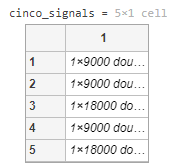

fprintf("Cantidad de señales normales y con arritmia")

Cantidad de señales normales y con arritmia

summary(Labels)

     A       738 
     N      5050 


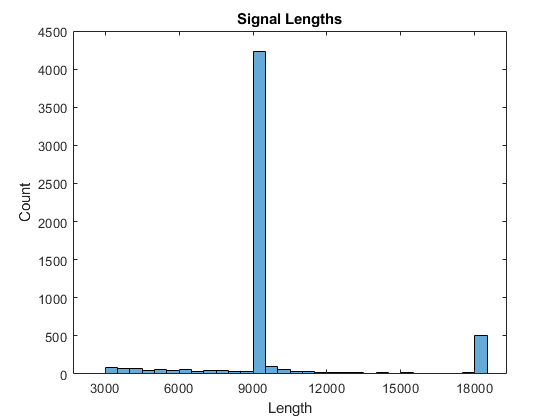

plotSignalLengths(Signals)

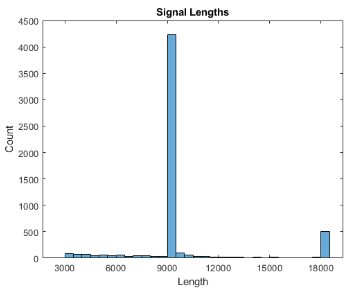

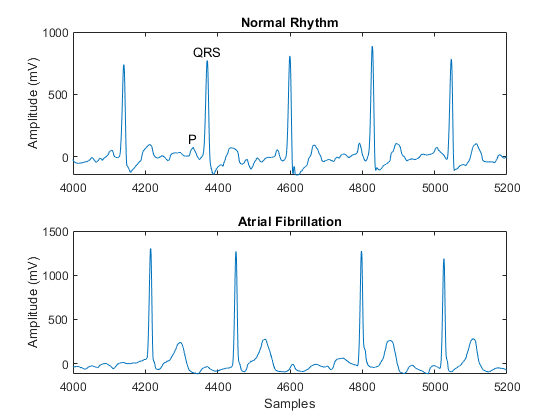

figure(2)
visualizeECGSignals(Signals)

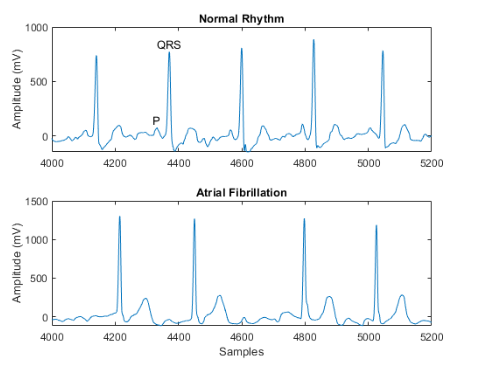

redimension = segmentSignals(Signals,Labels)

redimension = 5655×1 cell array
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}
    {1×9000 double}


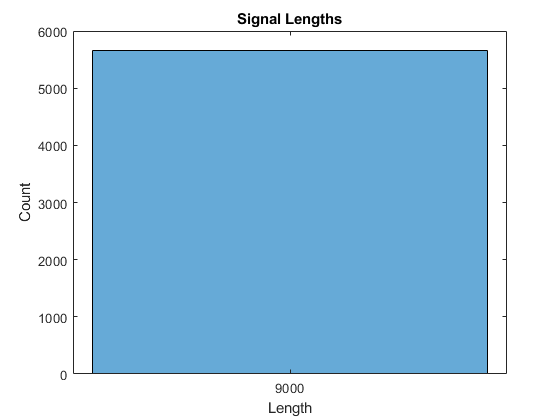

figure(3)
plotSignalLengths(redimension) 

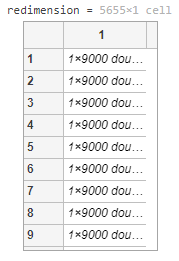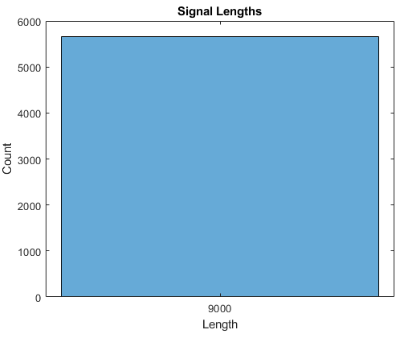

**Extraer Características**

Con el fin de mejorar la precisión del modelo que se entrena, se utilizarán las siguientes variables:

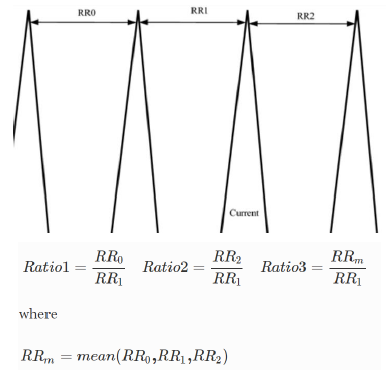

Además se agregan 2 caracteristicas mas las cuales son la amplitud de los picos R a partir de los dos canales de señal en la base de datos por lo tanto se tienen 8 caracteristicas en total.

**Cargar Datos de Características**

Se cargan los datos de las caracteristicas que se utilizan para el entrenamiento del modelo, luego se guardan los nombres de cada caracteristica en la variable "variableNames"

load ECG_ML_Features_DK.mat
variableNames = ECGFeatures_DK.Properties.VariableNames;

**Preparar Datos para el Entrenamiento**

Se dividen los datos en dos subconjuntos el 80% de los datos se guardan en una variable llamada "TrainData" los cuales nos sirven para el entrenmiento del modelo, el resto de los datos se guardan en la variable "TestData" los cuales nos sirven para evaluar el rendimiento del modelo entrenado.

n = length(ECGFeatures_DK.Variables);
partition = cvpartition(n,"Holdout",0.2);

idxTrain = training(partition);
TrainData = ECGFeatures_DK(idxTrain,:);

idxTest = test(partition);
TestData = ECGFeatures_DK(idxTest,:);

**Entrenar usando Classification Learner**

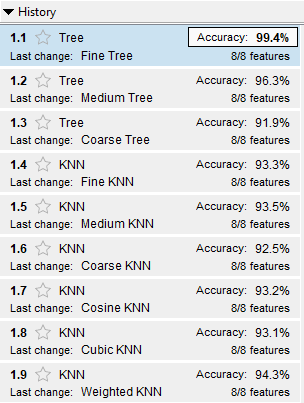

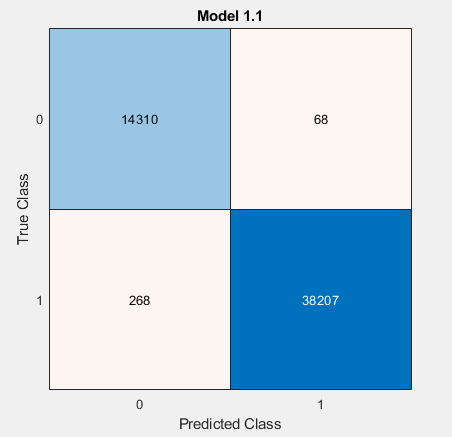

Luego de analizar los diferentes modelos, se concluye que el modelo mas acertado es el 1.1, ya que su precisión fue la mas alta y su matriz de confusión fue la que menos falsos negativos y verdaderos positivos.

**Evaluar el Modelo Entrenado**

Luego de identificar el modelo con las mejores caracteristicas de prediccón, lo exportamos mediante la funcion llamada "tranClassifier2", e ingresamos los datos de prueba con el fin de verificar el funcionamiento de dicho modelo, para lo cual se obtiene:

[trainedClassifier, validationAccuracy] = trainClassifier2(TestData)

trainedClassifier = struct with fields:
            predictFcn: @(x)treePredictFcn(predictorExtractionFcn(x))
     RequiredVariables: {'R1'  'R2'  'R3'  'RR0'  'RR1'  'RR2'  'rAmplitude1'  'rAmplitude2'}
    ClassificationTree: [1×1 ClassificationTree]
                 About: 'This struct is a trained model exported from Classification Learner R2020a.'
          HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see How to predict using an exported model.'


validationAccuracy = 0.9899

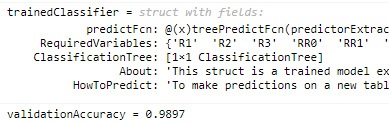

Podemos observar que se obtubo una precisión del 98.97% en la prediccón.

Se puede concluir que al momento de generar un modelo el cual identificara la arritmia cardiaca a parir de señales ECG, cuando se combina conocimientos de dominio medico y procesamiento de señales, se pueden obtener mejores caracteristicas las cuales nos ayuden a entrenar de una manera satisfactoria dichos modelos, incluso al ser pocas caracteristicas sin embargo pueden representar de una mejor manera lo que se busca identificar en las señales.